% clc
% vidReader = VideoReader('visiontraffic.avi','CurrentTime',11);
% opticFlow = opticalFlowLK('NoiseThreshold',0.009);
% 
% h = figure;
% movegui(h);
% hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
% hPlot = axes(hViewPanel);
% cmap = colormap("jet")
% 
% while hasFrame(vidReader)
%     frameRGB = readFrame(vidReader);
%     frameGray = im2gray(frameRGB);
%     flow = estimateFlow(opticFlow,frameGray);
%     imshow(frameRGB)
%     hold on
% %     plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10,'Parent',hPlot);
%     imshow(flow.Magnitude, 'Parent',hPlot, Colormap=cmap)
%     hold off
%     pause(10^-3)
% end

dcmHandler = scripts.dicomHandler.DICOMHandler();
dcmHandler.readDICOMDIR();
[dcmInfo, dcmImg] = dcmHandler.getPreview();
dcmImgs = medfilt3(dcmHandler.readAllImage());

[u,v] = scripts.opticalFlowHandler.lkofloop(dcmImgs, 'd');

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    15

    12

    13

    14

    16

    17

    18

    19

    24

    23

    22

    20

    21

    28

    27

    25

    26

    29

    31

    30



uv = sqrt(u.*u + v.*v);
size(uv)

ans =    384   384    31


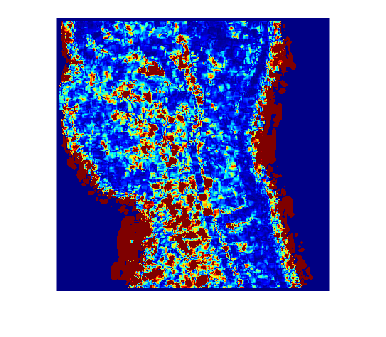

cmap = colormap("jet");

for i = 1:size(uv, 3)
    imshow(uv(:,:,i), Colormap=cmap)
    
    pause(10^-3)
end


% 
% 
% 
opticalFlowInstance = opticalFlowLK("NoiseThreshold", 10)

opticalFlowInstance =   opticalFlowLK のプロパティ:

    NoiseThreshold: 10


% 
% h = figure;
% movegui(h);
% hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
% hPlot = axes(hViewPanel);
% cmap = colormap("jet");
% 
% for i = 1:size(dcmImgs, 3)
%     flow = estimateFlow(opticalFlowInstance, dcmImgs(:,:,i));
%     imshow(dcmImgs(:,:,i))
%     hold("on")
%     imshow(flow.Magnitude, Colormap=cmap)
%     hold("off")
%     
%     pause(10^-3)
% end

